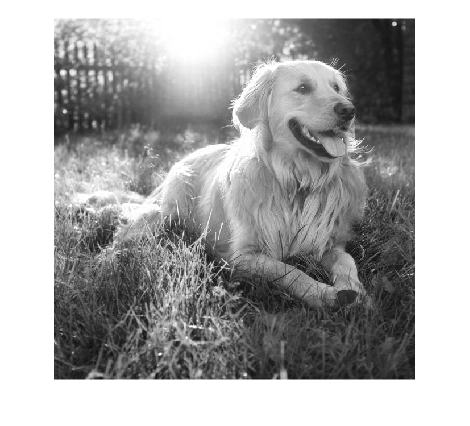



img = imread("squaredog.jpg");
imshow(img(:,:,1));

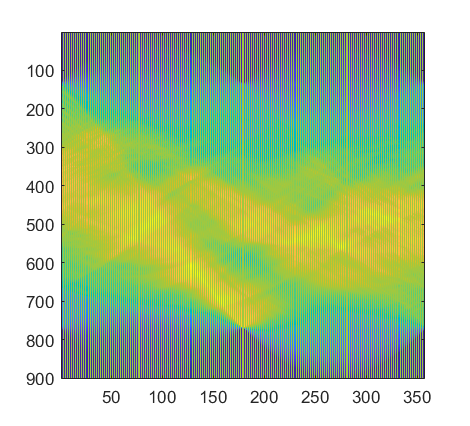


angles = 1:0.5:179;

R = img(:,:,1);

A = radon(R,angles);
%I = dct2(A);
%I(50:end,50:end) = 0;\
%imagesc(I);
%A = idct2(I);

%A(:,1:90) = flip(A(:,1:90),1);
A(:,1:2:end) = rand()*100000;
imagesc(A);

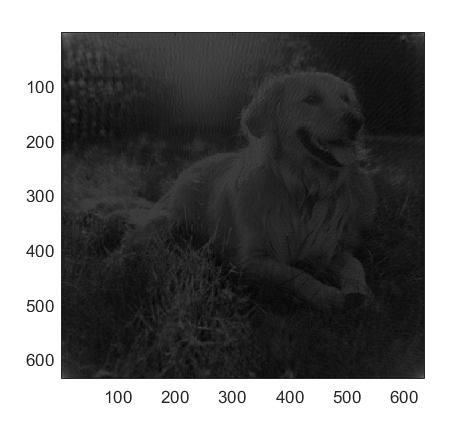


R = iradon(A,[]);

imagesc(R);
colormap(gray);